# Calculate Spherical Harmonics

Spherical harmonics arise in the solution to Laplace's equation and are used to represent functions defined on the surface of a sphere. Use `legendre` to compute and visualize the spherical harmonic for $Y_3^2$.

The equation for spherical harmonics includes a term for the Legendre function, as well as a complex exponential:


$$Y_l^m(\theta,\phi) = \sqrt{\frac{\left(2l+1\right) \left(l-m\right)!}{4 \pi \left(l+m\right)!}} P_l^m(\cos \theta) e^{i m \phi}, \qquad -l\le m \le l.$$


First, create a grid of values to represent all combinations of $-\frac{\pi }{2}\le \theta \le \frac{\pi }{2}\;$ (altitude angle) and $0\le \phi \le 2\pi$ (azimuthal angle).

dx = pi/60;
alt = -pi/2:dx:pi/2;
az = 0:dx:2*pi;
[phi,theta] = meshgrid(az,alt);

Calculate $P_l^m \left(\cos \;\theta \;\right)$ on the grid for $l=3$.

l = 5;
Plm = legendre(l,cos(theta));

Since `legendre` computes the answer for all values of $m$, `Plm` contains some extra function values. Extract the values for $m=2$ and discard the rest. Use the `reshape` function to orient the results as a matrix with the same size as `phi` and `theta`.

m = 3;
P32 = reshape(Plm(m+1,:,:), size(phi));

Calculate the spherical harmonic values for $Y_3^2$.

a = (2*l+1)*factorial(l-m);
b = 4*pi*factorial(l+m);
C = sqrt(a/b);
Y32 = C .* P32 .* exp(1i*m*phi);

Convert to Cartesian coordinates and plot the spherical harmonic for $Y_3^2$ using only the real values.

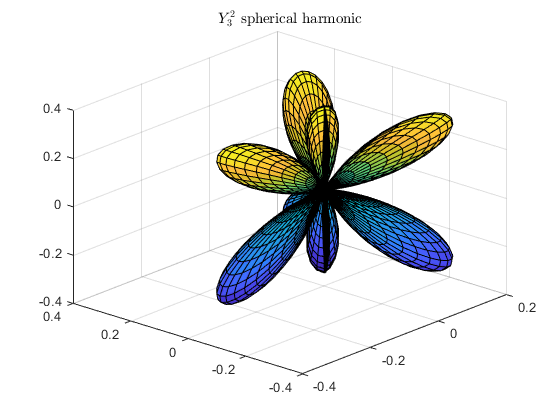

[Xm,Ym,Zm] = sph2cart(phi, theta, real(Y32));
surf(Xm,Ym,Zm)
title('$Y_3^2$ spherical harmonic','interpreter','latex')

*Copyright 2018 The MathWorks, Inc.*